# Solutions to Computer Assignment 0

clear; close all; clc;

## Problem 1

Consider the optimization problem that has been implemented in Matlab as follows:

clear
f = [-3 -2];
A = [2 1; 1 1; 1 0];
b = [10 8 4];
Aeq = [];
beq = [];
lb = [0 0];
ub = [];
x = linprog(f,A,b,Aeq,beq,lb,ub)

Optimal solution found.



x =      2
     6


From the linprog documentation:

`x = linprog(f,A,b,B,c,l,u); `

solves the problem


$$\min \; f^\top x\\ \text{s.t.} \;\; Ax \leq b\\ \;\;\;\;\;\;  Bx = c\\ \;\;\;\;\;\; l \leq x \leq u$$


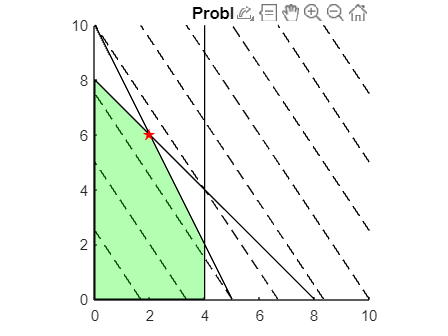

x1Vector = linspace(0,10,10);
x2Vector = linspace(0,10,10);

figure;
hold on
% objective function
contour(x1Vector,x2Vector,-2 * x2Vector' * ones(1,10) - 3 * ones(10,1) * x1Vector,'k--')
% constraints
plot(x1Vector,10-2*x1Vector,'k');
plot(x1Vector,8-x1Vector,'k');
line([4 4],[0 10],'color','k');
axis equal
xlim([0 10])
ylim([0 10])
% feasible domain
fill([0 4 4 2 0 0],[0 0 2 6 8 0],'g','FaceAlpha',.3)
% optimum
scatter(x(1),x(2),72,'red','filled','pentagram')

axis equal
xlim([0 10])
ylim([0 10])
title('Problem 1')

## Problem 2

clear
H = [2 0; 0 2];
f = [-10 -10];
A = [2 1; 1 1; 1 0];
b = [10 8 4];
Aeq = [];
beq = [];
lb = [0 0];
ub = [];
%options = optimset('quadprog');
%options = optimset(options, 'Algorithm','active-set');
%options = optimoptions('quadprog');
%options = optimoptions(options, 'Algorithm','active-set');
%x = quadprog(H,f,A,b,Aeq,beq,lb,ub,[],options)
x = quadprog(H,f,A,b,Aeq,beq,lb,ub)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     3.0000
    4.0000


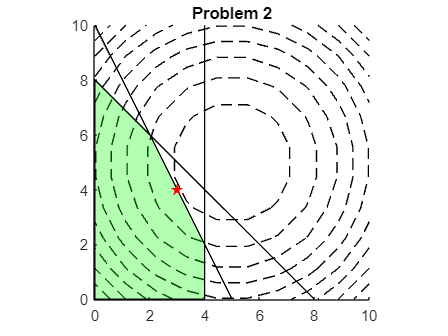

x1Vector = linspace(0,10,10);
x2Vector = linspace(0,10,10);

figure;
hold on
% objective function
contour(x1Vector,x2Vector,(x2Vector'.^2 -10 * x2Vector') * ones(1,10) + ones(10,1) * (x1Vector.^2 -10 * x1Vector) + 50,'k--')
% constraints
plot(x1Vector,10-2*x1Vector,'k');
plot(x1Vector,8-x1Vector,'k');
line([4 4],[0 10],'color','k');
% feasible domain
fill([0 4 4 2 0 0],[0 0 2 6 8 0],'g','FaceAlpha',.3)
% optimum
scatter(x(1),x(2),72,'red','filled','pentagram')

axis equal
xlim([0 10])
ylim([0 10])
title('Problem 2')

## Problem 3

x0 = [3 4];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0 0];
ub = [];
%options = optimset('fmincon');
%options = optimset(options, 'Algorithm', 'interior-point'); 
options = optimoptions('fmincon');
options = optimoptions(options, 'Algorithm', 'interior-point');
x = fmincon(@objfun,x0,A,b,Aeq,beq,lb,ub,@nonlcon,options)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     2.0000    2.0000


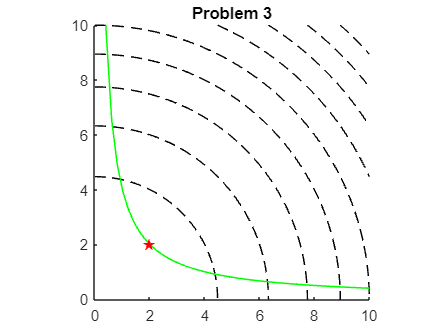

x1Vector = linspace(0,10,50);
x2Vector = linspace(0,10,50);

figure;
hold on
% objective function
contour(x1Vector,x2Vector,(0.5 * x2Vector'.^2) * ones(1,50) + ones(50,1) * (0.5 * x1Vector.^2),'k--')
% constraints
plot(x1Vector,4./x1Vector,'k');
axis equal
xlim([0 10])
ylim([0 10])
% feasible domain
plot(x1Vector,4./x1Vector,'g','LineWidth',1);
% optimum
scatter(x(1),x(2),72,'red','filled','pentagram')

axis equal
xlim([0 10])
ylim([0 10])
title('Problem 3')

## Problem 4

clear
x0 = [-1 1];
options = optimoptions('fminunc');
options = optimoptions(options, 'Algorithm', 'quasi-newton'); 
x_fminunc = fminunc(@banana,x0,options)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x_fminunc =     1.0000    1.0000



x0 = [-1 1];
%options = optimoptions('fminsearch');
%options = optimoptions(options, 'Algorithm', 'quasi-newton'); 
x_fminsearch = fminsearch(@banana,x0)

x_fminsearch =     1.0000    1.0000


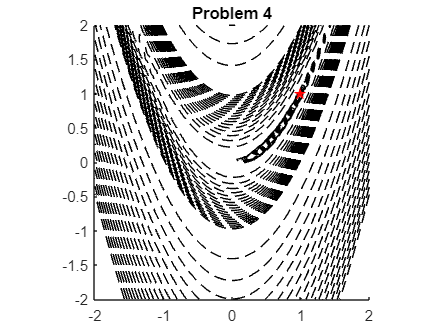

x1Vector = linspace(-2,2,50);
x2Vector = linspace(-2,2,50);

figure;
hold on
% objective function
contour(x1Vector,x2Vector,ones(50,1) * (1 - x1Vector).^2 + 100 * (x2Vector' * ones(1,50) - ones(50,1) * x1Vector.^2).^2,[0:.1:.9,1:5:100,200:100:2000],'k--')
% optimum
scatter(x_fminsearch(1),x_fminsearch(2),72,'red','filled','pentagram')

axis equal
xlim([-2 2])
ylim([-2 2])
title('Problem 4')

Functions

function [f] = objfun(x)
    f = 0.5*x(1)^2 + 0.5*x(2)^2;
end

function [g,h] = nonlcon(x)
    g = [];
    h = x(1)*x(2) - 4;
end

function [f] = banana(x)
x1 = x(1); x2 = x(2);
f = (1-x1)^2 + 100*(x2-x1^2)^2;
end